% Main script to run Experiment 1: SIFT + SVM (Whole Image)

## Clean environment

close all;
clear variables;
clc;

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);

## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  




disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder);

    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  




disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  



## Resize image datastores and combine them with the labels

trainCDS = resizeCombineDatastore(trainingImageDS);
valCDS = resizeCombineDatastore(validationImageDS);
testCDS = resizeCombineDatastore(testImageDS);

## Show images

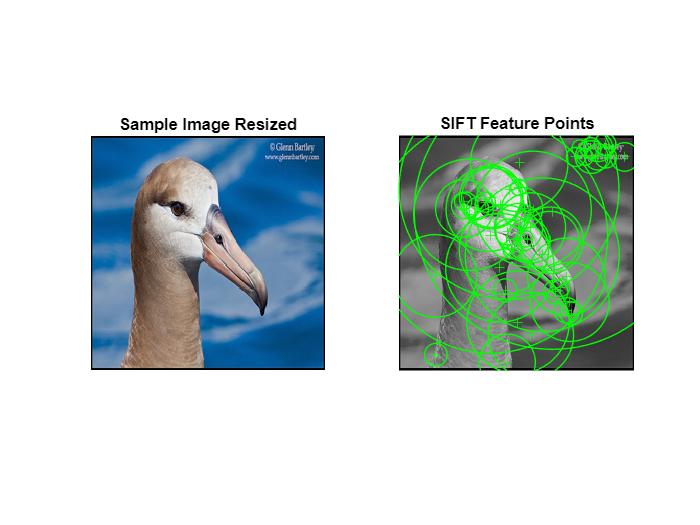

showImageFeatures(trainCDS)

## Extract SIFT features

numFeatures = 50;
maxFeatures = 100;

[trainingFeatures, trainingLabels] = extractSIFTFeaturesFromDatastore(trainingImageDS, numFeatures, maxFeatures);
[testFeatures, testLabels] = extractSIFTFeaturesFromDatastore(testImageDS, numFeatures, maxFeatures);

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Train classifier

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.
Copying objective function to workers...
Done copying objective function to workers.
|===============================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |              |
|===============================================================================================================|
|    1 |       8 | Best   |     0.94745 |       27.63 |     0.94745 |     0.94745 |     0.077149 |      0.22813 |


The error message follows:
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.
|    2 |       6 | Accept |     0.94745 |      28.011 |     0.87988 |     0.88682 |       325.73 |       3.3239 |
|    3 |       6 | Accept |     0.94745 |      27.709 |     0.87988 |     0.88682 |    0.0014612 |       2.2311 |
|    4 |       6 | Best   |     0.87988 |      27.651 |     0.87988 |     0.88682 |       3.4473 |       24.908 |
|    5 |       8 | Accept |     0.94745 |      36.923 |     0.87988 |     0.87989 |       17.628 |      0.61675 |
|    6 |       8 | Best   |     0.87838 |      36.835 |     0.87838 |     0.87905 |       3.0939 |       24.449 |
|    7 |       7 | Best   |     0.87237 |      37.191 |     0.87237 |      0.8755 |        3.923 |       27.243 |
|    8 |       7 | Accept |     0.88739 |      36.864 |     0.87237 |      0.8755 |       3.3798 |       15.841 |
|    9 |       8 | Accept | 

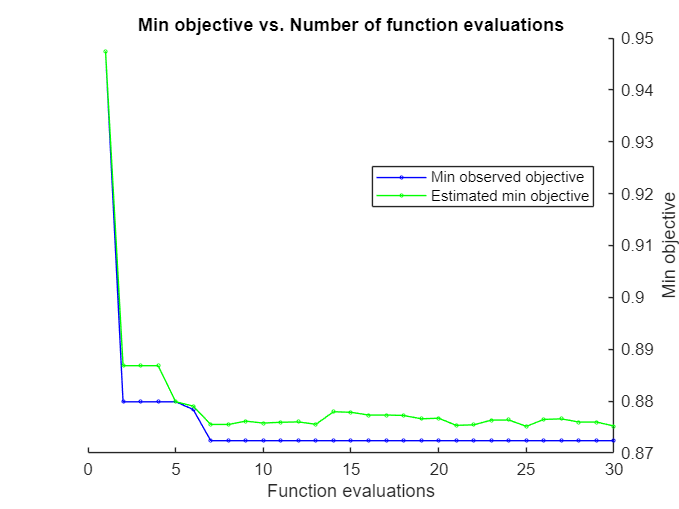

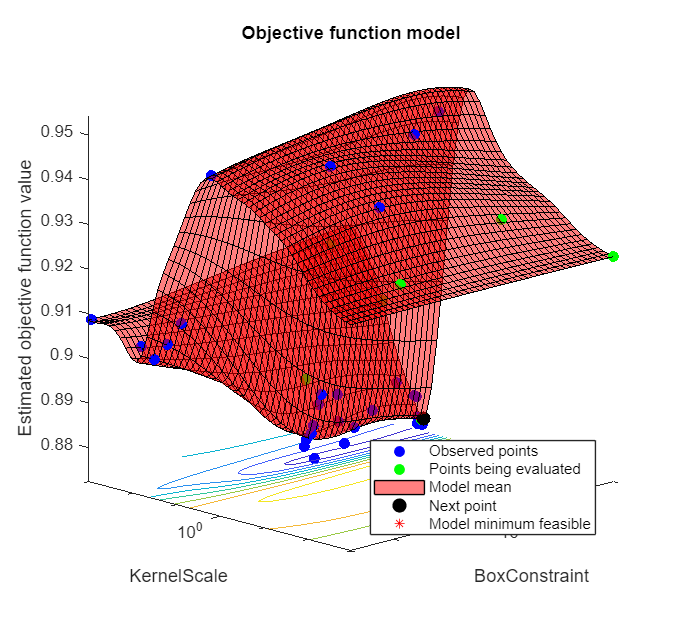

SVMClassifier = trainSVMClassifier(trainingFeatures, trainingLabels);

## Evaluate

[accuracy, predictions] = evaluateClassifier(SVMClassifier, testFeatures, testLabels);

## Plot confusion matrix

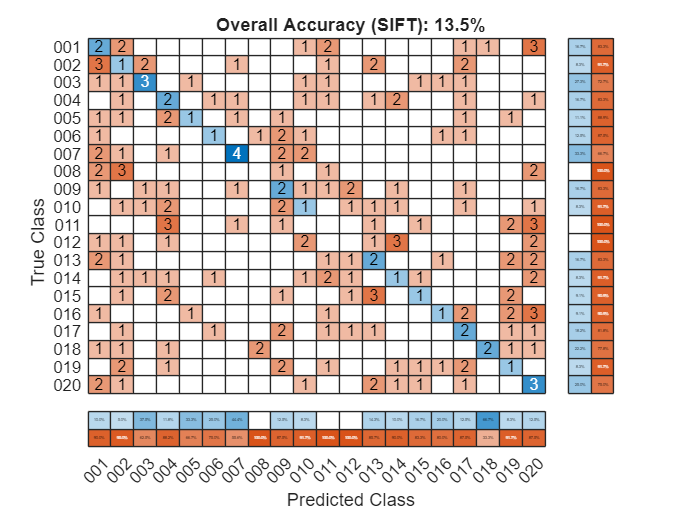

plotConfusionMatrix(testLabels, predictions, "Overall Accuracy (SIFT): " + string(round(accuracy*100, 1)) + "%");